# AAE 301 HW 4

## QUESTION 1

% creating function
t = linspace(0, 2*pi);
f = sin(1.5*t);

% finding ak's
a0 = 2/(3*pi);
psi0 = 1;

p = 0;
n = 20;
ak_list = [];
k_list = -n:1:n;

for k=k_list
    if k == 0
        ak = a0;
    else
        ak = -6 / (pi*(4*k^2 - 9));
    end
    ak_list = [ak_list, ak];
    psik = exp(-1i*k*t);
    p = p + ak*psik;
end

disp('this should small');

this should small


disp(norm(imag(p)));

   2.3076e-16



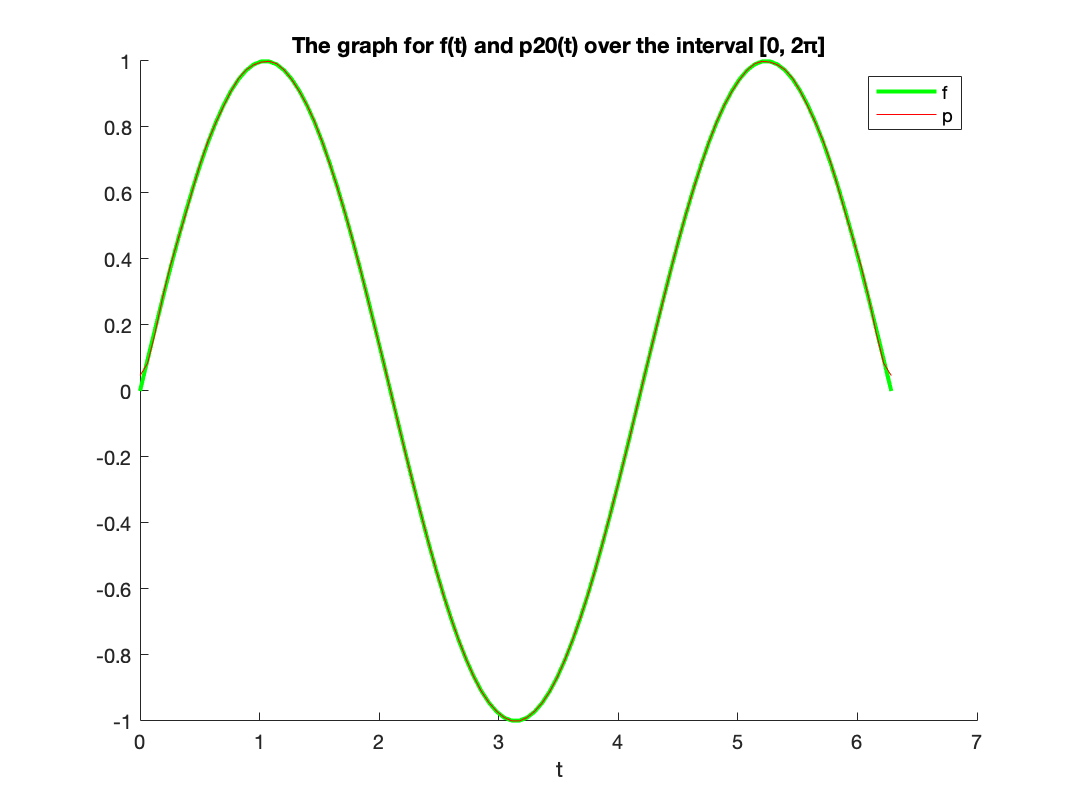

p = real(p);

% plot function and approximation
figure(1);
clf;
hold on;
plot(t, f, 'g', 'LineWidth', 2);
plot(t, p, 'r');
xlabel('t');
legend('f', 'p')
title("The graph for f(t) and p20(t) over the interval [0, 2π]")
hold off;

## QUESTION 3

% PART A

% creating function
t = linspace(0, 2*pi);
f = t.*sin(t);

% finding ak's
a0 = -1;
psi0 = 1;

p = 0;
n = 20;
ak_list = [];
k_list = -n:1:n;
pn_norm_sq = 0;

for k=k_list
    if k == 0
        ak = a0;
    elseif k == 1
        ak = -1/4 + (pi/2)*1i;
    elseif k == -1
        ak = -1/4 - (pi/2)*1i;
    else
        ak = 1/(k^2 - 1);
    end
    ak_list = [ak_list, ak];
    psik = exp(-1i*k*t);
    %psik = cos(k*t);
    p = p + ak*psik;
    pn_norm_sq =  pn_norm_sq + abs(ak)^2;
end

disp('this should small');

this should small


disp(norm(imag(p)));

   5.9635e-16



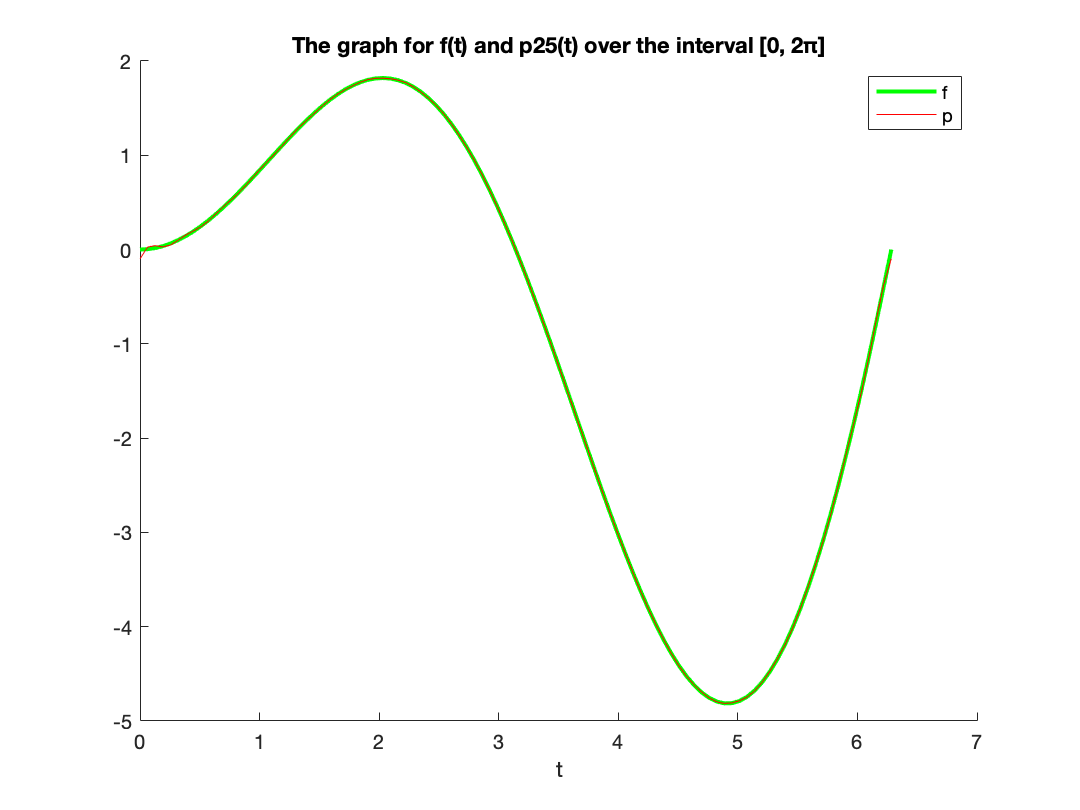

p = real(p);

% plot function and approximation
figure(2);
clf;
hold on;
plot(t, f, 'g', 'LineWidth', 2);
plot(t, p, 'r');
xlabel('t');
legend('f', 'p')
title("The graph for f(t) and p25(t) over the interval [0, 2π]")
hold off;

% PART B
norm_sq = (2*pi^2)/3 - 1/4;

error = sqrt(norm_sq - pn_norm_sq);
fprintf("Error: %f", error)

Error: 0.008804